## Data sampling for ID

### trim data

start_time = duration('00:02:16.148000');
end_time = duration('00:02:16.14850');

% Create a timerange object
ts_range = timerange(start_time, end_time);

% Index both pitch_in and elevator using the rows subscript
elevator_trim = pitch_in.pitch_in(ts_range,:) - elevator.elevator(ts_range,:)

elevator_trim = 0.1368

throttle_trim = throttle_in.throttle_in(ts_range,:) - throttle.throttle(ts_range,:)

throttle_trim = 0.3304

airspeed_trim = ind_airspeed.indicated_airspeed(ts_range,:)

airspeed_trim = single
14.7282

alt_trim = alt.alt(ts_range,:)

alt_trim = single
235.1120

pitch_rate_trim = q.q(ts_range,:)

pitch_rate_trim = 0.7505

alpha_trim = alpha.alpha(ts_range,:)

alpha_trim = single
0.9369

### step input

% t_start = duration('00:03:35.096000');
% t_end_s = duration('00:03:45.068000');
% t_end_p = duration('00:03:55.040000');
% 
% % sampling the short period inputs - 5 secs
% % Create a timerange object
% ts_range = timerange(t_start, t_end_s);
% throttle_s_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
% elevator_s_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
% q_s_step = q.q(ts_range,:); 
% aoa_s_step = alpha.alpha(ts_range,:);
% 
% %smapling phugoid inputs - atleast 10 secs
% % Create a timerange object
% ts_range = timerange(t_start, t_end_p);
% throttle_p_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
% elevator_p_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
% vel_p_step = ind_airspeed.indicated_airspeed(ts_range,:); 
% alt_p_step = alt.alt(ts_range,:);

### doublet input

t_start = duration('00:07:22.680852');
t_end_s = duration('00:07:29.088347');
t_end_p = duration('00:07:34.428884');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_doublet = q.q(ts_range,:); 
aoa_s_doublet = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_doublet = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_doublet = alt.alt(ts_range,:);

### sine sweep input

t_start = duration('00:05:06.251568');
t_end_s = duration('00:05:27.876800');
t_end_p = duration('00:05:27.876800');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_sine = q.q(ts_range,:); 
aoa_s_sine = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_sine = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_sine = alt.alt(ts_range,:);

## System ID script - step

% iodelay = 0;
% u1 = throttle_s_step;
% u2 = elevator_s_step;
% u3 = throttle_p_step;
% u4 = elevator_p_step;
% airspeed_trim = vel_p_step(1,1);
% alt_trim = alt_p_step(1,1);
% pitch_rate_trim = q_s_step(1,1);
% alpha_trim = aoa_s_step(1,1);
% y3 = q_s_step - pitch_rate_trim;
% y1 = double(vel_p_step - airspeed_trim);
% y4 = double(aoa_s_step - alpha_trim);
% y5 = double(alt_p_step - alt_trim);

### MIMO identification - short period mode

% u = [u2];
% y = [y3 y4];
% np = [2;2];%[3 3; 2 2];
% nz = [1;2]%[1 1; 2 2];
% data = iddata(y,u);
% set(data,'InputName',{'Elevator deflection'},'OutputName',{'Pitch rate', 'Angle of Attack'})
% plot(data)
% sys1= tfest(data,np,nz,iodelay);
% compare(data,sys1)

### MIMO identification - Phugoid mode

% u = [u4];
% y = [y1 y5];
% np = [2;2];%[3 2; 3 3];
% nz = [1;2];%[1 1; 2 2];
% data = iddata(y,u);
% set(data,'InputName',{'Elevator deflection'},'OutputName',{'Velocity', 'Altitude'});
% plot(data)
% sys2= tfest(data,np,nz,iodelay);
% compare(data,sys2)

### system identified

% G1 = tf([sys1; sys2]);  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height
% bode(G1)

## System ID script - doublet

iodelay = 0;
u1 = throttle_s_doublet-0.05;
u2 = elevator_s_doublet;
u3 = throttle_p_doublet-0.05;
u4 = elevator_p_doublet;
airspeed_trim = vel_p_doublet(1,1);
alt_trim = alt_p_doublet(1,1);
pitch_rate_trim = q_s_doublet(1,1);
alpha_trim = aoa_s_doublet(1,1);
y1 = double(vel_p_doublet - airspeed_trim);
y3 = q_s_doublet - pitch_rate_trim;
y4 = double(aoa_s_doublet - alpha_trim);
y5 = double(alt_p_doublet - alt_trim);

### MIMO identification - short period mode

u = [u2];
y = [y3];
np = [2];%[3 3; 2 2];
nz = [1]%[1 1; 2 2];

nz = 1

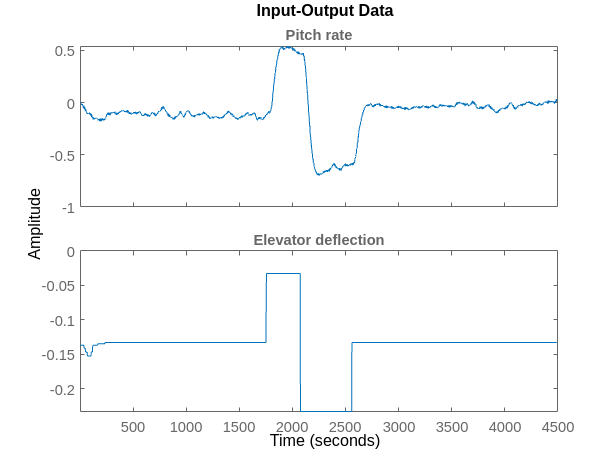

data = iddata(y,u);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Pitch rate'})
plot(data)

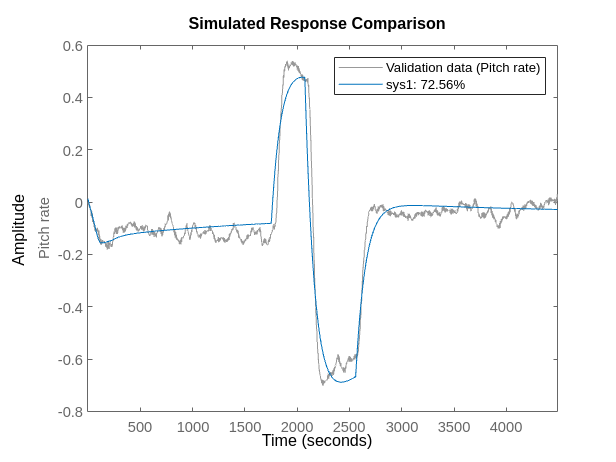

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

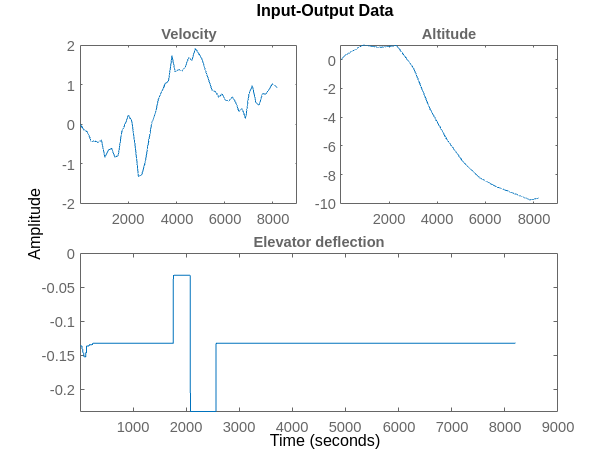

u = [u4];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

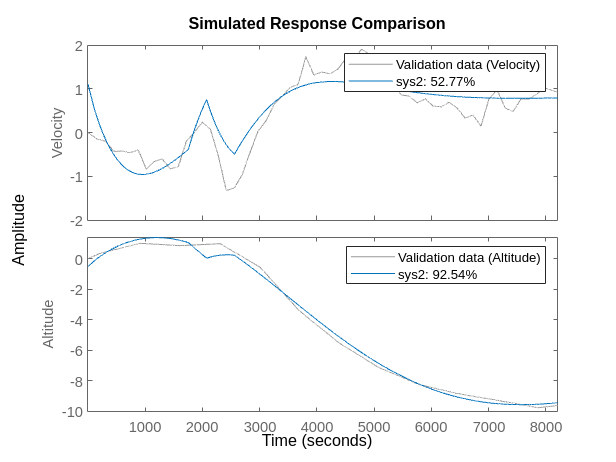

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G2_ef = tf([sys1; sys2])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G2_ef =
 
  From input "Elevator deflection" to output...
                   0.06915 s + 1.894e-06
   Pitch rate:  ---------------------------
                s^2 + 0.01129 s + 5.712e-06
 
                 0.03459 s - 9.732e-06
   Velocity:  ----------------------------
              s^2 + 0.001613 s + 1.595e-06
 
                 -0.02186 s + 1.425e-05
   Altitude:  -----------------------------
              s^2 + 0.0003949 s + 2.725e-07
 
Continuous-time transfer function.



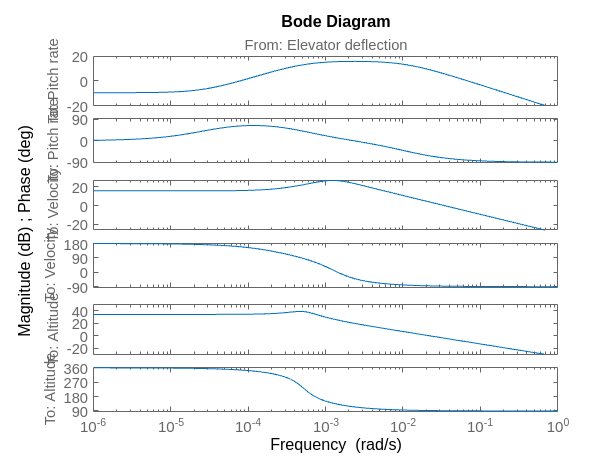

bode(G2_ef)

## System ID script - sine sweep

iodelay = 0;
u1 = throttle_s_sine;
u2 = elevator_s_sine;
u3 = throttle_p_sine;
u4 = elevator_p_sine;
airspeed_trim = vel_p_sine(1,1);
alt_trim = alt_p_sine(1,1);
pitch_rate_trim = q_s_sine(1,1);
alpha_trim = aoa_s_sine(1,1);
y1 = double(vel_p_sine - airspeed_trim);
y3 = q_s_sine - pitch_rate_trim;
y4 = double(aoa_s_sine - alpha_trim);
y5 = double(alt_p_sine - alt_trim);

### MIMO identification - short period mode

u = [u2];
y = [y3];
np = [2];%[3 3; 2 2];
nz = [1]%[1 1; 2 2];

nz = 1

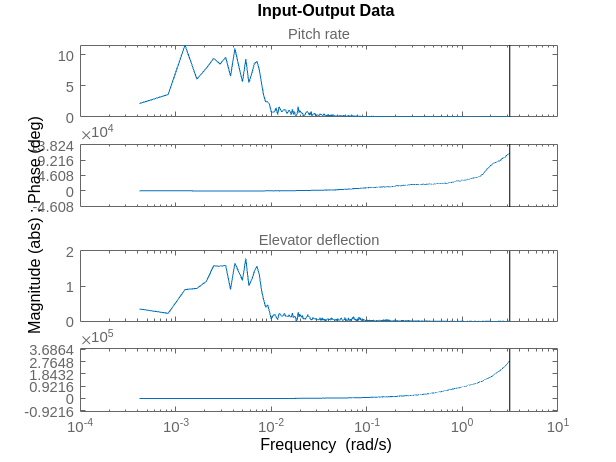

data = iddata(y,u);
data = fft(data);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Pitch rate'})
plot(data)

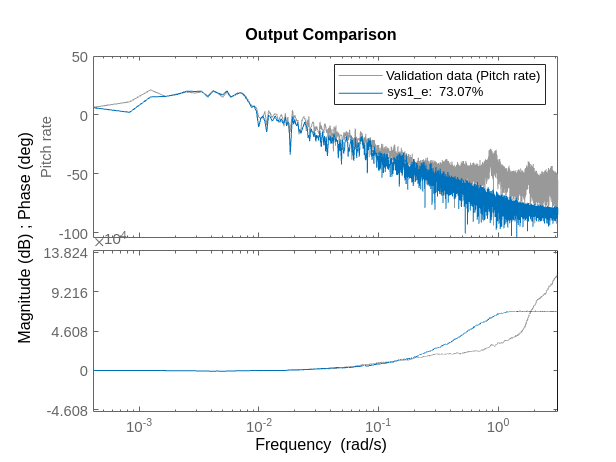

sys1_e= tfest(data,np,nz,iodelay);
compare(data,sys1_e)

### MIMO identification - Phugoid mode

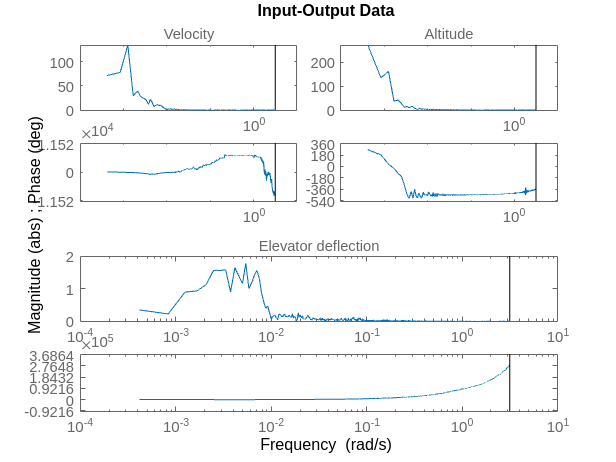

u = [u4];
y = [y1 y5];
np = [2;2];%[3 2; 3 3];
nz = [1;1];%[1 1; 2 2];
data = iddata(y,u);
data = fft(data);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Velocity', 'Altitude'})
plot(data)

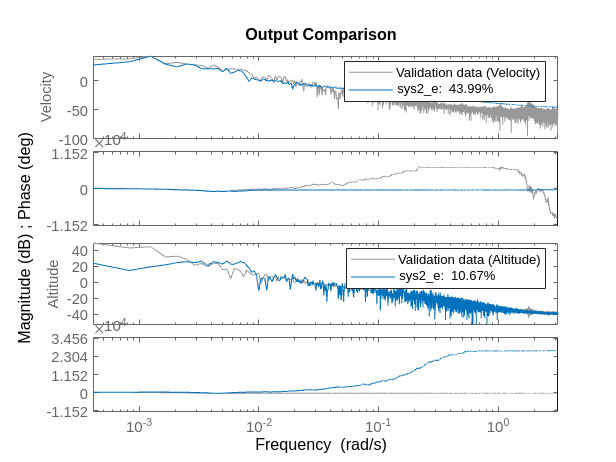

sys2_e= tfest(data,np,nz,iodelay);
compare(data,sys2_e)

### system identified

G3_ef = tf([sys1_e; sys2_e])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G3_ef =
 
  From input "Elevator deflection" to output...
                   0.07179 s - 3.386e-07
   Pitch rate:  ---------------------------
                s^2 + 0.01096 s + 1.892e-06
 
                  0.02829 s - 2.951e-06
   Velocity:  -----------------------------
              s^2 + 0.0002794 s + 1.442e-06
 
                 -3.425 s + 3.307e-05
   Altitude:  --------------------------
              s^2 + 0.2868 s - 9.104e-06
 
Continuous-time transfer function.



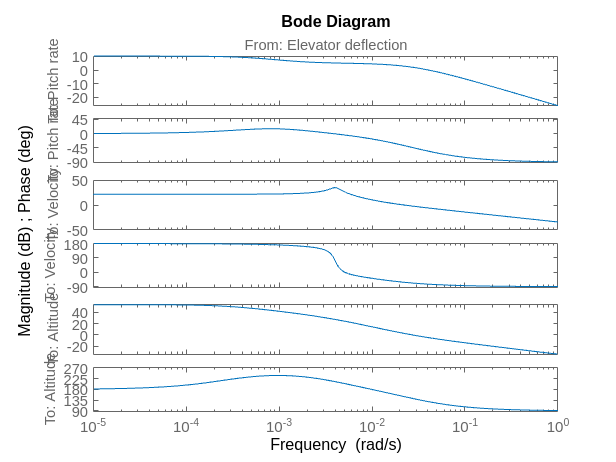

bode(G3_ef)